close all; clear; clc;

# 90% Settling Time Script testing

**filename**: PercentAll_Inc10_20180702.mlx

**keywords:** 

**file created by:** {20170702, Edmonds}

**last updated on:** {20170702}

**primary purpose: **The purpose of this data set is to run more tests to try to understand the function and application of the 90% settling time script

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

This script also has a max accelreation and settling time output

**functions:** [C_T], [C_P], [C_Q]

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.0022928591928233;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

load('PercAllinc10.mat');
time = PercAllinc10(:,1);          % [sec]
ESC_us = PercAllinc10(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = PercAllinc10(:,3);             % [ft.lbf]
T = PercAllinc10(:,4);             % [lbf]
Input_V = PercAllinc10(:,5);       % [Volts]
Input_A = PercAllinc10(:,6);       % [Amps]
rot_speed = PercAllinc10(:,7);     % [rad/sec]
P_in_W = PercAllinc10(:,8);        % [Watts]
P_out_W = PercAllinc10(:,9);        % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;     % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;       % [ft.lbf/sec]

Motor_Eff = PercAllinc10(:,10);    % [%]
Prop_Eff = PercAllinc10(:,11);     % [lbf/Watts]
Overall_Eff = PercAllinc10(:,12);  % [lbf/Watts]  
Motor_Temp = PercAllinc10(:,13);   % [F]

Settling_time = PercAllinc10(:,14); % [s]
Max_Acc = PercAllinc10(:,15);      % [RPM]

## Thrust, Power, and Torque Coefficents

[C_T] = Thrust_Coefficient(T,p,area,rot_speed,radius);
[C_P] = Power_Coefficient(P_out,p,area,rot_speed,radius);
[C_Q] = Torque_Coefficient(Q,p,area,rot_speed,radius);

## Plots

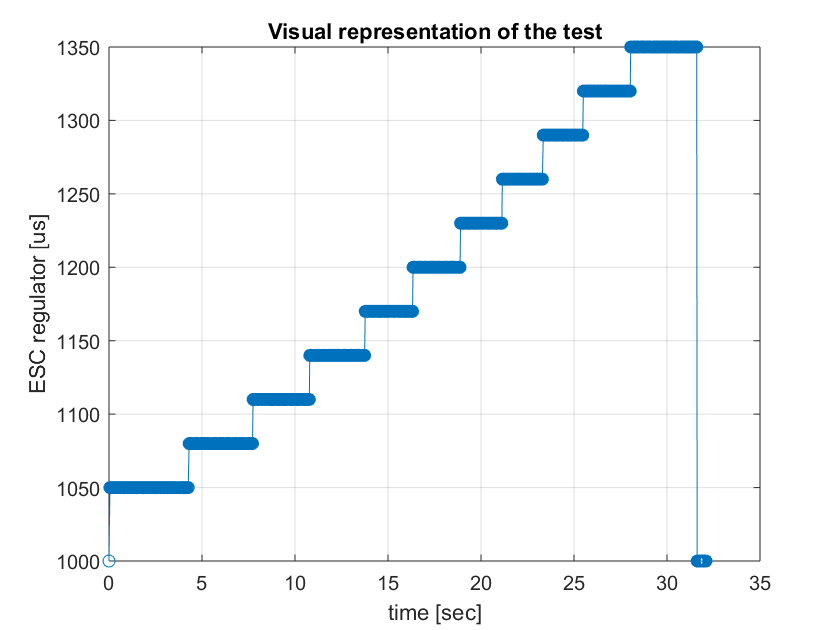

figure(1)
plot(time, ESC_us, 'o-'); title('Visual representation of the test');
xlabel('time [sec]'); ylabel('ESC regulator [us]'); grid('on');

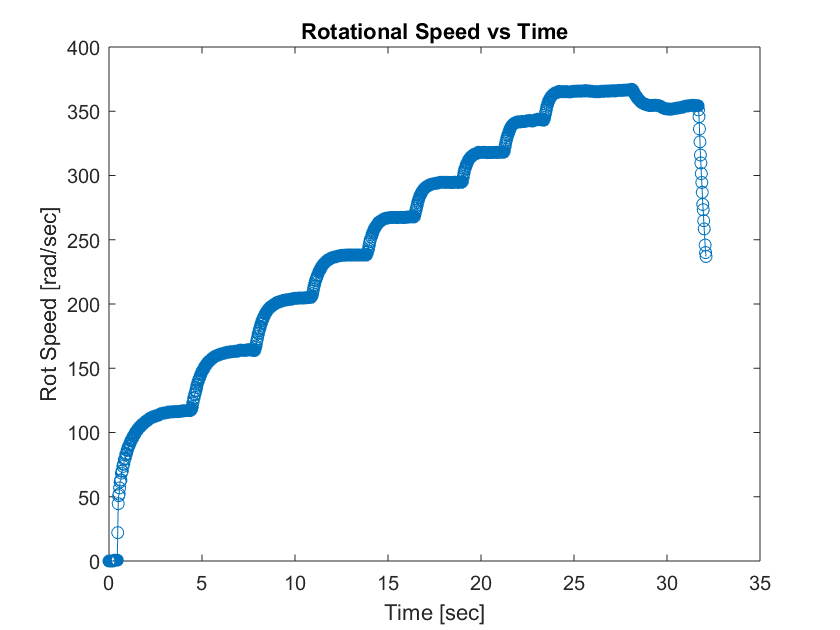

figure(2)
plot(time, rot_speed, 'o-');
title('Rotational Speed vs Time'); xlabel('Time [sec]'); ylabel('Rot Speed [rad/sec]');

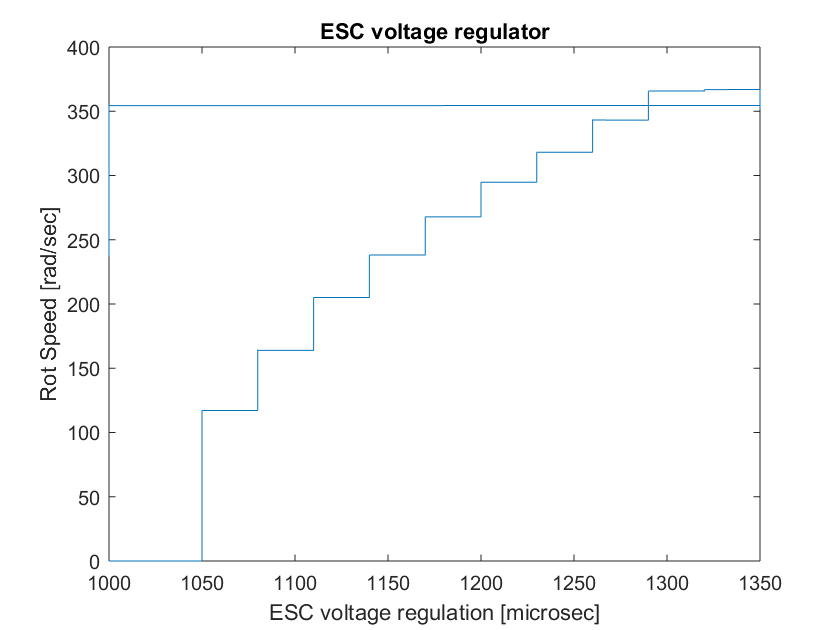

figure(3)
plot(ESC_us, rot_speed);
title('ESC voltage regulator'); xlabel('ESC voltage regulation [microsec]'); 
ylabel('Rot Speed [rad/sec]');

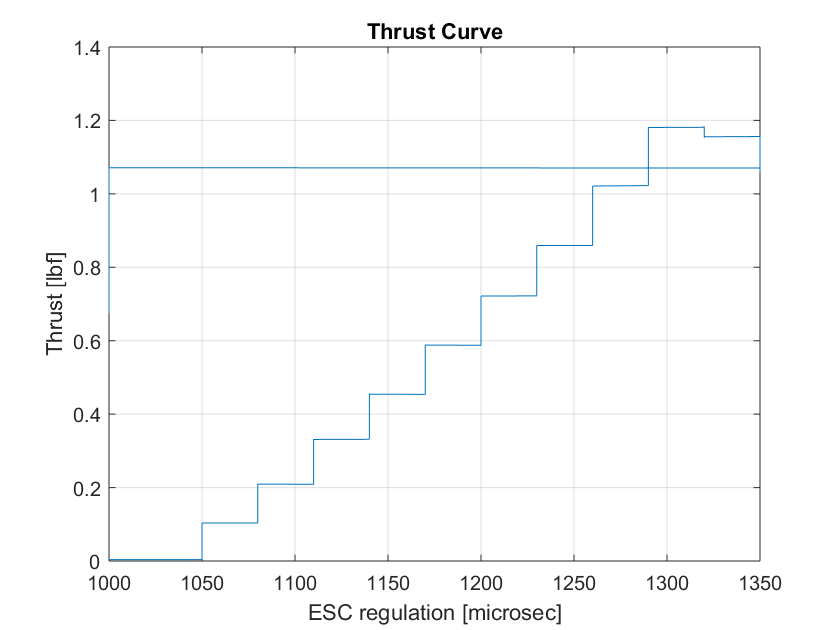

figure(4)
plot(ESC_us, T);
title('Thrust Curve'); xlabel('ESC regulation [microsec]'); ylabel('Thrust [lbf]'); 
grid('on'); ylim([0,1.4]);

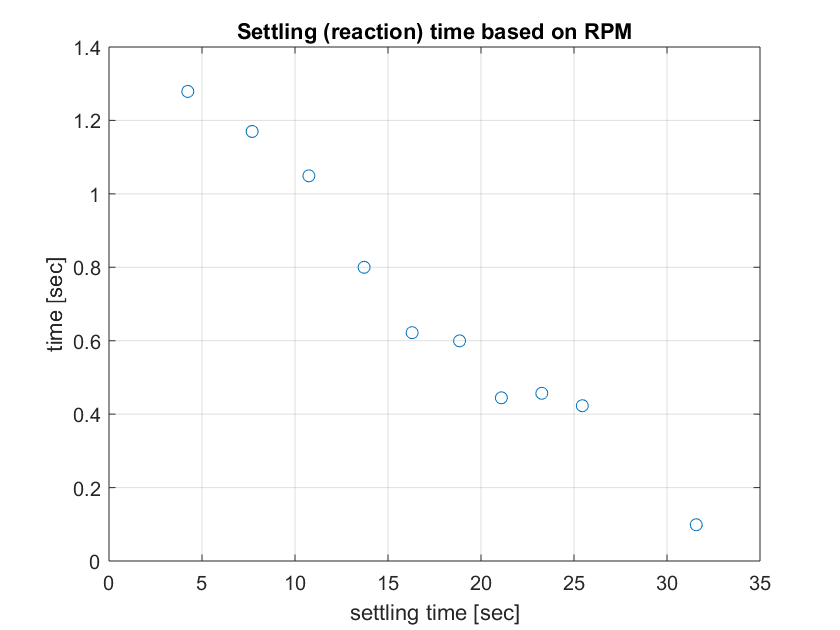

figure(5)
plot(time, Settling_time, 'o-'); title('Settling (reaction) time based on RPM')
xlabel('settling time [sec]'); ylabel('time [sec]'); grid('on');

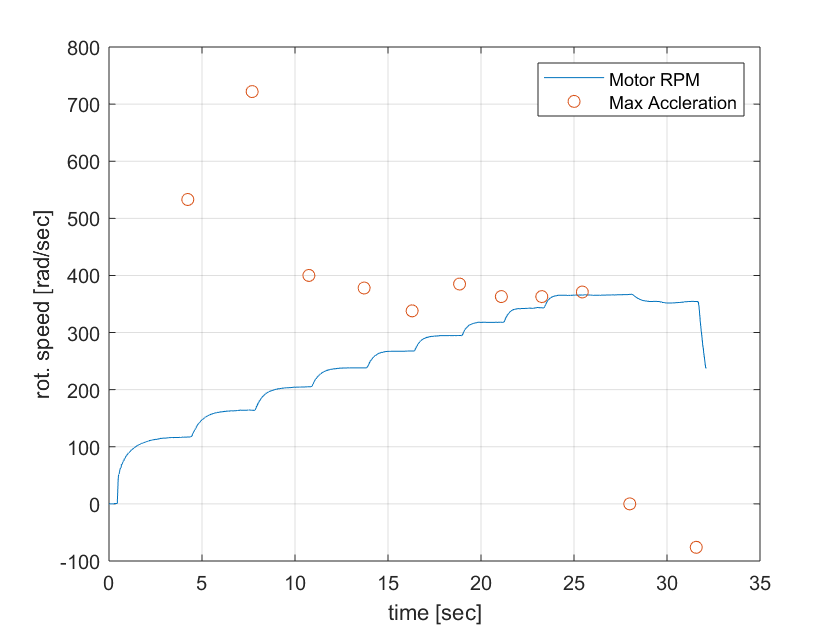

figure(6)
plot(time, rot_speed, time, Max_Acc, 'o');
xlabel('time [sec]'); ylabel('rot. speed [rad/sec]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');